### Load in data

data1 = load("LaskyThreshold_1.mat");
data2 = load("LaskyThreshold_2.mat");

### Prepare valid trials correct by color

redChanges = [data1.redChangesThisTrial, data2.redChangesThisTrial];
greenChanges = [data1.greenChangesThisTrial, data2.greenChangesThisTrial];

correct = [data1.trialCorrect, data2.trialCorrect];

correctRedChange = correct(logical(redChanges));
correctGreenChange = correct(logical(greenChanges));

perCorrectRedChange = sum(correctRedChange)/length(correctRedChange) * 100;
perCorrectGreenChange = sum(correctGreenChange)/length(correctGreenChange) * 100;

### Plot valid trials correct by color

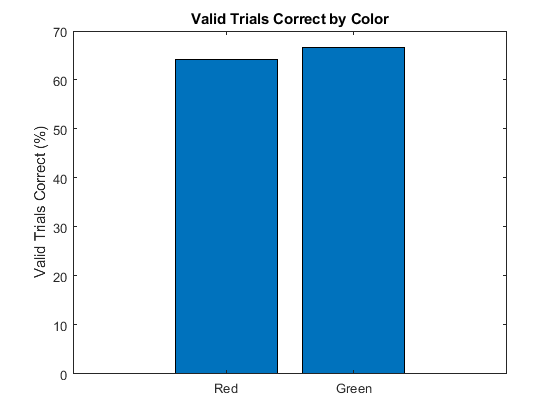

bar([perCorrectRedChange, perCorrectGreenChange])
title("Valid Trials Correct by Color")
xticklabels(["Red", "Green"])
ylabel("Valid Trials Correct (%)")

### Prepare valid trials correct by orientation change

orientationChange = abs([data1.orientationChangeThisTrial, data2.orientationChangeThisTrial]);
validTrial = [data1.valid, data2.valid];

correctSmallestChange = correct(validTrial == 1 & orientationChange == 0.6);
correctSmallChange = correct(validTrial == 1 & orientationChange == 0.8);
correctMedChange = correct(validTrial == 1 & orientationChange == 1);
correctBigChange = correct(validTrial == 1 & orientationChange == 2);
correctBiggerChange = correct(validTrial == 1 & orientationChange == 3);

perCorrectSmallestChange = sum(correctSmallestChange)/length(correctSmallestChange);
perCorrectSmallChange = sum(correctSmallChange)/length(correctSmallChange);
perCorrectMedChange = sum(correctMedChange)/length(correctMedChange);
perCorrectBigChange = sum(correctBigChange)/length(correctBigChange);
perCorrectBiggestChange = sum(correctBiggerChange)/length(correctBiggerChange);

### Plot valid trials correct by orientation change

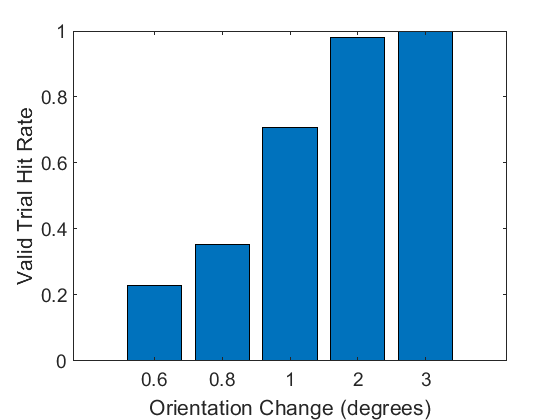

bar([perCorrectSmallestChange; perCorrectSmallChange; perCorrectMedChange; perCorrectBigChange; perCorrectBiggestChange])
xticklabels([0.6, 0.8, 1, 2, 3])
ax = gca;
ax.XAxis.FontSize = 14;
ax.YAxis.FontSize = 14;
xlabel("Orientation Change (degrees)", "FontSize", 16)
ylabel("Valid Trial Hit Rate", "FontSize", 16)
saveas(gcf, "Threshold Curve.png")